# Initialization

clear all
close all
addpath('FTgui')


Param = struct('siz',[],'tleng',[],'subwindow_size',[],'name',[],'fres',[]...
    ,'cut',[],'propor',[],'pathin',[],'pathout',[],'timestep',[]...
    ,'sigma',[],'strel',[],'register',[],'regsize',[],'nbpoints',[],'sizeview',[],'contour',[],'rec',[],'tsart',[]);

## Output folder location

Param.out_rootdir = {'\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\Confocal\'};

## List of folders to treat/folder to treat

%When multiple folders, write them like this:

Param.name = {'C:\Users\Melina\Documents\DOCTORAT\Matlab\2A\CAMILLE\Probleme\1\';
    'C:\Users\Melina\Documents\DOCTORAT\Matlab\2A\CAMILLE\Probleme\2\'};
% When one folder only is required, write it like this:

Param.name = {'\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\Confocal\im1\'};

## New and optional: input height map files

Param.heightmapfiles = [];
%Param.heightmapfiles = '//lfs.lifesci.dundee.ac.uk/lfs/cjw/Jason/cable detection/exp0245/h_map/';
%TODO additional height info from _info files metadata
Param.voxel = [1 1 1]; % x y z pixel sizes
                                               %need correct real-unit ratio of height steps
                                               % in heightmap files
                                               % to x y pixel size, from
                                               % microscopy metadata!

## Parameters you should change and that are NOT tunable with the user interface

Param.overlap = 0.5;                % Overlap between the sliding boxes
Param.tsart = 1;                % Beginning of the analysis
Param.tleng = 2;               % End of the analysis
Param.timestep = 1;         % Temporal average

## Parameters that ARE tunable with the user interface

Param.subwindow_size = 100;                % Size of the subwindows
Param.cut = 1;                       % Cut of the spectra
Param.propor =  0.02;          % Proportion of points to keep
Param.sigma = 0.3;              % Gaussian filter
Param.register = 0;             %   Save spectra if 1, 0 otherwise
Param.regsize = 0;              % Analysis in size required ?
Param.nbpoints = 30;          % Number of points to keep in the ellipse fit
Param.strel = 4;                % Strel of the spectra
Param.def_ellipse = 1;      % Use ellipse method for cell deformation

Param.zoom=3;

## Parameters that can be changed if desired

Param.scale = 150;                    % scaling for cell deformation

% name of the output folder created
Param.fres = ['results_', char(datetime('now', Format='dd-MM-yyyy''_''HH-mm-ss'))];

## Never change this

Param.contour=[];

## Creation of the output folder

Param.pathout = [Param.out_rootdir{1}, Param.fres , '/']; % path to result folder
if ~exist(Param.pathout,'dir')             % creation of result folder
    mkdir(Param.pathout)
end

## Visualization of the parameters

GUI_deformation_ft(Param)

Index exceeds the number of array elements. Index must not exceed 0.

Error in Position_gui (line 19)
AllX = 1:spacing:(Param.siz(2)- Param.subwindow_size);

Error in GUI_deformation_ft>calculregion (line 715)
[handles.Posi,handles.regl] = Position_gui(handles.Param);

Error in 

## Try new app

app1(Param)

'app1' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\jklebes001\myosin-cable-detection
    C:\Users\jklebes001

Change the MATLAB current folder or add its folder to the MATLAB path.

## Analysis alone if required

Please wait, computation of FT 1
Please wait, computation of FT 2
Computation of cell size, time: 1
Computation of cell size, time: 2
Computation of cell deformation, time: 1
Computation of cell deformation, time: 2
Computation of cell deformation, time: 1
Computation of cell deformation, time: 2
Representation of deformation map, time: 1


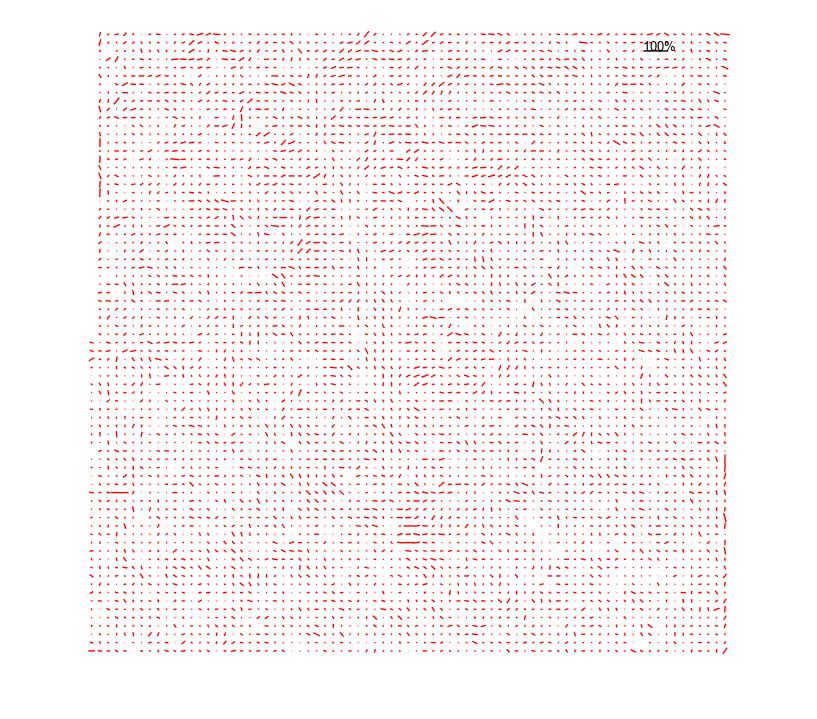

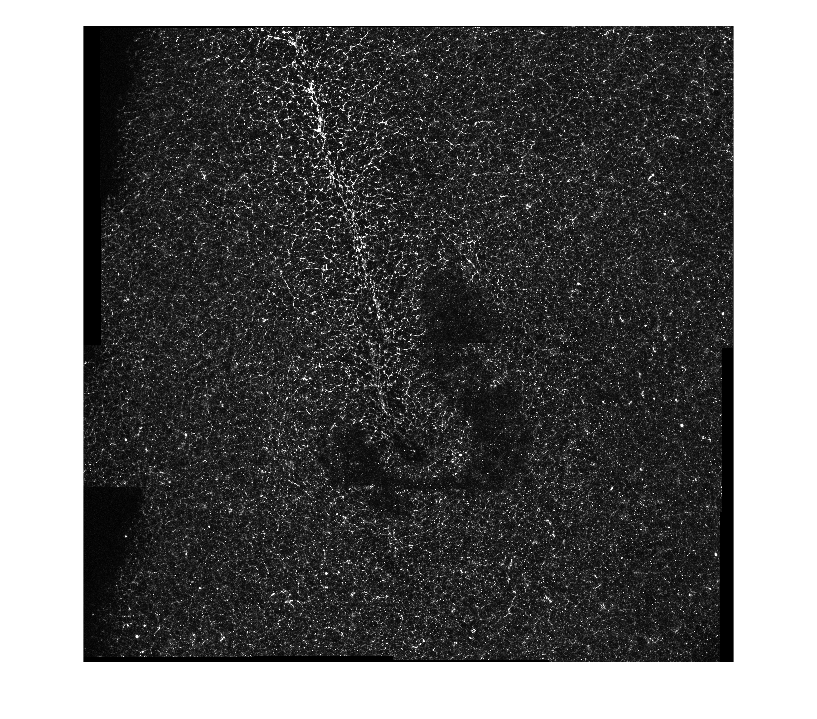

Representation of deformation map, time: 2


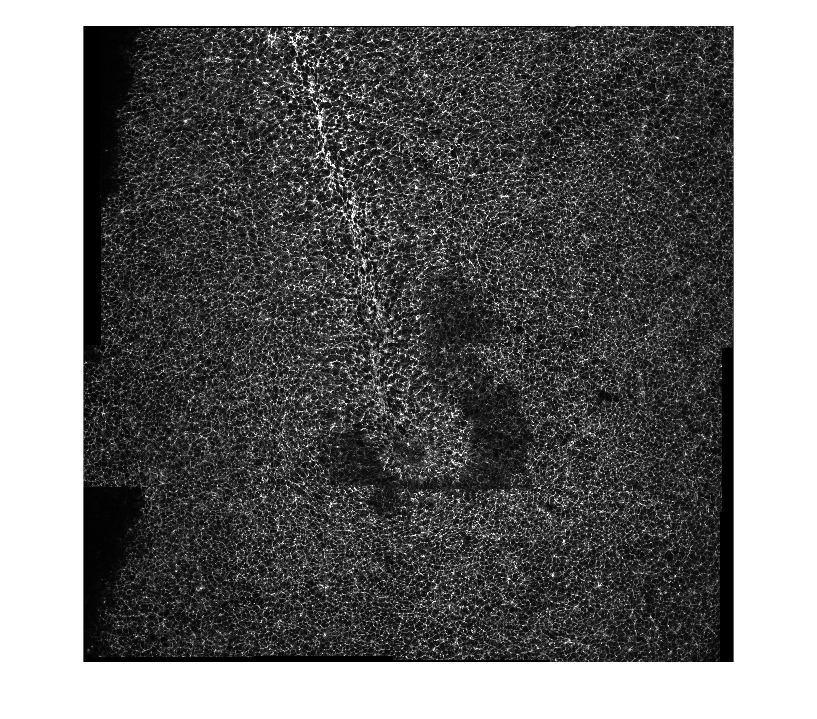

ans = struct with fields:
           regl: 5775
           Posi: [5775×2 double]
       im_regav: [1×1 struct]
             ci: 2
           numX: 77
           numY: 75
    tile_slopes: 0


full_analysis(Param)

%results will be found in output folder

## Save results

save([Param.pathout,'Param.mat'],'Param','-v7.3');